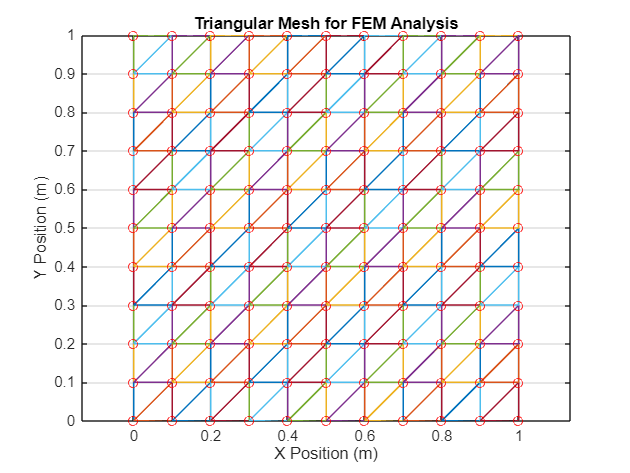

% Parameters
k = 50;                % Thermal conductivity (W/m.K)
Q = 1000;              % Heat input at center node
T_inf = 25;            % Ambient temp for convection
h = 10;                % Convection coefficient (W/m^2-K)
Nx = 10; Ny = 10;      % Grid size

% Generate structured mesh
L = 1;
dx = L / Nx;
dy = L / Ny;
[x_grid, y_grid] = meshgrid(0:dx:L, 0:dy:L);
nodes = [x_grid(:), y_grid(:)];
n_nodes = size(nodes,1);

% Element connectivity (triangulated squares)
elements = [];
for j = 1:Ny
    for i = 1:Nx
        n1 = i + (j-1)*(Nx+1);
        n2 = n1 + 1;
        n3 = n1 + (Nx+1);
        n4 = n3 + 1;
        elements = [elements;
                    n1 n2 n4;
                    n1 n4 n3];
    end
end


%% Plot the mesh
figure;
trimesh(elements, nodes(:,1), nodes(:,2), 'LineWidth', 1);
title('Triangular Mesh for FEM Analysis');
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis equal;
grid on;

%% Add annotations (optional)
hold on;
plot(nodes(:,1), nodes(:,2), 'ro', 'MarkerSize', 6); % Show nodes as red circles


% Print mesh statistics
fprintf('Mesh details:\n');

Mesh details:


fprintf('Number of nodes: %d\n', n_nodes);

Number of nodes: 121


fprintf('Number of elements: %d\n', size(elements,1));

Number of elements: 200



n_elements = size(elements,1);

% Global matrices
K = zeros(n_nodes);
F = zeros(n_nodes,1);

% Assembly
for e = 1:n_elements
    idx = elements(e,:);
    coords = nodes(idx,:);
    x = coords(:,1); y = coords(:,2);
    
    A = polyarea(x, y);
    b = [y(2)-y(3); y(3)-y(1); y(1)-y(2)];
    c = [x(3)-x(2); x(1)-x(3); x(2)-x(1)];
    ke = (k / (4*A)) * (b*b' + c*c');
    K(idx, idx) = K(idx, idx) + ke;
end

% Convection BC on bottom edge (y = 0)
tol = 1e-6;
bottom_nodes = find(abs(nodes(:,2)) < tol);
bottom_edges = [];

% Find boundary edges (node pairs)
for i = 1:length(bottom_nodes)-1
    n1 = bottom_nodes(i);
    n2 = bottom_nodes(i+1);
    if abs(nodes(n1,1) - nodes(n2,1)) <= dx + 1e-6
        bottom_edges = [bottom_edges; n1 n2];
    end
end

% Add convection contribution
for e = 1:size(bottom_edges,1)
    n1 = bottom_edges(e,1);
    n2 = bottom_edges(e,2);
    x1 = nodes(n1,1); y1 = nodes(n1,2);
    x2 = nodes(n2,1); y2 = nodes(n2,2);
    L_edge = sqrt((x2 - x1)^2 + (y2 - y1)^2);

    ke_conv = h * L_edge / 6 * [2 1; 1 2];
    fe_conv = h * T_inf * L_edge / 2 * [1; 1];

    K([n1 n2],[n1 n2]) = K([n1 n2],[n1 n2]) + ke_conv;
    F([n1 n2]) = F([n1 n2]) + fe_conv;
end

% Apply point heat source at center
center_coord = [0.5, 0.5];
[~, center_node] = min(vecnorm(nodes - center_coord, 2, 2));
F(center_node) = F(center_node) +Q;

% Solve (all nodes are free now)
T = K \ F;


%% Display results
disp('Nodal Temperatures:');

Nodal Temperatures:


for i = 1:n_nodes
    fprintf('Node %d (%0.1f, %0.1f): T = %.2f°C\n', i, nodes(i,1), nodes(i,2), T(i));
end

Node 1 (0.0, 0.0): T = 124.72°C
Node 2 (0.0, 0.1): T = 126.67°C
Node 3 (0.0, 0.2): T = 128.50°C
Node 4 (0.0, 0.3): T = 130.18°C
Node 5 (0.0, 0.4): T = 131.64°C
Node 6 (0.0, 0.5): T = 132.81°C
Node 7 (0.0, 0.6): T = 133.64°C
Node 8 (0.0, 0.7): T = 134.18°C
Node 9 (0.0, 0.8): T = 134.50°C
Node 10 (0.0, 0.9): T = 134.66°C
Node 11 (0.0, 1.0): T = 134.71°C
Node 12 (0.1, 0.0): T = 124.77°C
Node 13 (0.1, 0.1): T = 126.73°C
Node 14 (0.1, 0.2): T = 128.58°C
Node 15 (0.1, 0.3): T = 130.29°C
Node 16 (0.1, 0.4): T = 131.79°C
Node 17 (0.1, 0.5): T = 132.97°C
Node 18 (0.1, 0.6): T = 133.79°C
Node 19 (0.1, 0.7): T = 134.29°C
Node 20 (0.1, 0.8): T = 134.58°C
Node 21 (0.1, 0.9): T = 134.72°C
Node 22 (0.1, 1.0): T = 134.76°C
Node 23 (0.2, 0.0): T = 124.90°C
Node 24 (0.2, 0.1): T = 126.88°C
Node 25 (0.2, 0.2): T = 128.80°C
Node 26 (0.2, 0.3): T = 130.62°C
Node 27 (0.2, 0.4): T = 132.25°C
Node 28 (0.2, 0.5): T = 133.51°C
Node 29 (0.2, 0.6): T = 134.25°C
Node 30 (0.2, 0.7): T = 134.62°C
Node 31 (0.2, 0.8):

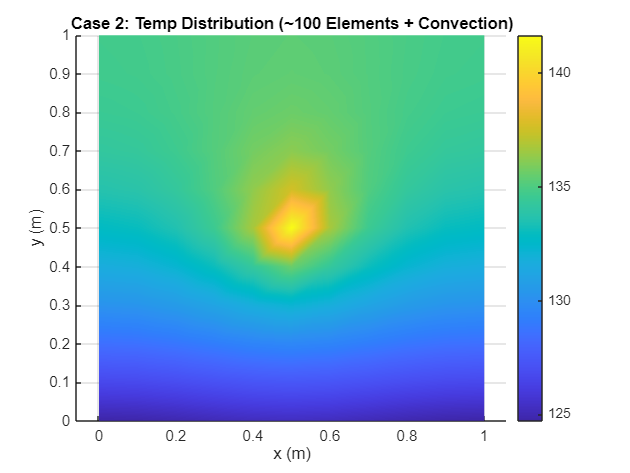


% Plot temperature distribution
figure;
trisurf(elements, nodes(:,1), nodes(:,2), T, 'FaceColor','interp');
colorbar;
title('Case 2: Temp Distribution (~100 Elements + Convection)');
xlabel('x (m)'); ylabel('y (m)'); zlabel('Temperature (°C)');
view(2); axis equal; shading interp;

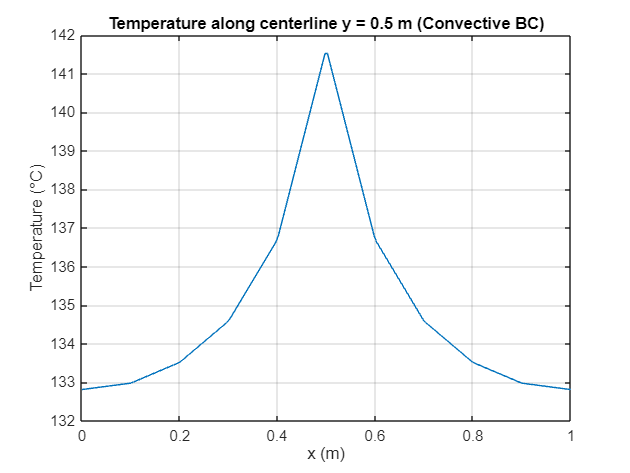


% Plot centerline
x_line = linspace(0, 1, 200);
T_line = griddata(nodes(:,1), nodes(:,2), T, x_line, 0.5 * ones(size(x_line)));

figure;
plot(x_line, T_line, '-');
title('Temperature along centerline y = 0.5 m (Convective BC)');
xlabel('x (m)'); ylabel('Temperature (°C)');
grid on;